# 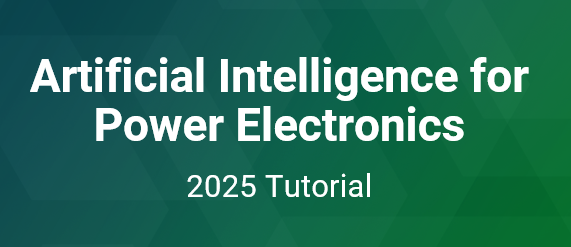

# **Demo 1: Shallow Neural Network for Regression **

### The goal is to use an Artificial Neural Network to estimate the firing angles required for Selective Harmonic Minimization in Cascaded Multilevel Inverters with varying DC sources.

# 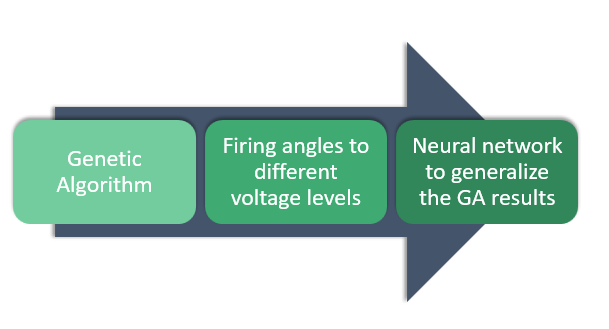

Figure 1: Neural newtork pre-processing.

## **1º step: **Load the data to train the Neural Network

In this problem, the inputs consist of 1,922 samples of two voltage levels. 

The outputs are six optimal switching angles for each voltage combination, generated by the Genetic Algorithm. 

These six angles correspond to the control of the fundamental frequency and five harmonics (3rd, 5th, 7th, 9th, and 11th).

clear variables
load data_ann; %training data
s=rng;
rng (s); %To ensure that we all train the identical neural network.

% Plotting the NN training data
for a = 1:2
    subplot(2,1,a); 
    hold on
    if a == 1
        ylabel('[V]');
        legendInfo = {'V1 values', 'V2 values'};
        plot(inputs(1,:), 'LineWidth', 1.2); % Plot V1
        plot(inputs(2,:), 'LineWidth', 1.2); % Plot V2
    else
        ylabel('[Degrees]');
        legendInfo = {'A1','A2','A3','A4','A5','A6'};
        for j = 1:6
            plot(outputs(j,:), 'LineWidth', 1.2); % Plot A1 to A6
        end
    end
    grid on; 
    xlim([1,size(inputs,2)])
    xlabel('Samples')
    legend(legendInfo);
end

## **2º step: **Neural Network configuration

The following code opens the Matlab Neural Network Fitting app interface.

nftool; % training system

*Using the interface, you can train a two-layer feed-forward network with sigmoid activation functions for the hidden neurons and a linear activation function for the output. The network can be trained using your choice of Levenberg-Marquardt backpropagation, Bayesian Regularization, or Scaled Conjugate Gradient algorithms. For this particular problem, a two-layer neural network provides sufficient capacity for good generalization. To customize the network's characteristics and training process, command-line coding can be used.* *See Matlab *[*documentation*](https://www.mathworks.com/help/deeplearning/gs/fit-data-with-a-neural-network.html)*.*

## **3º step: Setting the Neural Network Inputs and Outputs for training**

With the NN Fitting tool open, click on 'Import.' Under 'Predictors,' select 'inputs,' and under 'Responses,' select 'outputs.' 

In the 'Observations in' field, select 'Columns,' since we have 1,922 samples, each with 2 elements (voltages), and the outputs consist of 1,922 samples of 6 switching angles. 

Click 'OK.

## **4º step: Input data split**

To ensure that the model generalizes well to unseen data, the input and output data must be split into training, validation, and test sets. 

We will use the default option of 70% for training, 15% for validation, and 15% for testing.

## **5º step: Hidden Layer Size**

A two-layer Neural Network is being trained in this demo. 

In this step, you can adjust the number of neurons in the hidden layer. 

For this problem, 8 neurons will be used. Enter '8' in the 'Layer size' field.

## **6º step: Training Algorithm**

Choose Levenberg-Marquardt as the training algorithm and click 'Train.

## **7º step: Save as function and compare the estimate vs. target values**

Now, let's save the neural network. 

Click on 'Export Network Function for MATLAB Compiler' and save the file as 'ann8.' 

This file will be used to evaluate the real expected outputs and the estimated outputs generated by the neural network. 

Analyze the network's performance by comparing its output with the target values:

% Simulation of the ANN
estimated = ann8(inputs);

% Represents each input combination
index = 1:1922;

figure(1)
% Plotting angles
for a = 1:6
    subplot(2,3,a); 
    plot(index, outputs(a,:), 'r', index, estimated(a,:), 'b'); 
    grid on; 
    ylabel(['angle ', num2str(a)]); 
    legend('Desired','Estimated', 'location', 'NorthWest')
end

## **8º step**: Deploy the Neural Network to Simulink and open the main model

Click on 'Export to Simulink.' The neural network will be created in the Simulink environment. 

Now that the neural network is trained and in good shape, proceed to the Simulink model. 

open('demo1_model')

When the model opens, copy and paste the neural network into the main model in the marked area. 

As expected, the inputs to the neural network are the voltage levels, and the outputs are the six angles, which are fed into the control logic.

## **10º step**: Simulate the model

Now, simulate the model for 10 cycles by clicking the 'Run' button. 

## **11º step**: Check the Results: FFT Analysis

Double-click the grey button under the output voltage scope to open the FFT analysis. 

In the 'FFT Settings' field, set the 'Number of cycles' to 10 and the 'Max frequency' to 2000. 

In the 'Frequency Axis' section, select 'Harmonic order.' 

Finally, click on 'Compute FFT.'

Even with the voltage change that occurred within a 0.1-second interval, it is evident that the 3rd, 5th, 7th, 9th, and 11th harmonics are significantly reduced compared to other harmonic orders.

## **Instructor Team:**

Joao O. P. Pinto   – Oak Ridge National Laboratory – Knoxville, pintoj@ornl.gov 

Burak Ozpineci    –  Oak Ridge National Laboratory – Knoxville, burak@ornl.gov

Marcio Kimpara   – Oak Ridge National Laboratory – Knoxville, magrikimparm@ornl.gov

Pedro Ribeiro      –  Oak Ridge National Laboratory – Knoxville, ribeirope@ornl.gov

Renata Kimpara  –  Oak Ridge National Laboratory – Knoxville, rezendedacor@ornl.gov

Feel free to contact us.

*We would like to thank Faete 'JT' Filho from the Savannah River National Laboratory and Raymundo Cordero, Associate Professor at the Federal University of Mato Grosso do Sul, Brazil.*